# MATLAB Onramp:

## Part 1: Multiple Outputs, Documentation, and Plots

Two new functions **randi()** & **size() **are introduced in this section. You can access the documentation via the Help button in the upper right corner of the MATLAB interface to learn more about the inputs and outputs of these function. Alternatively, you can type the command "doc" followed by the name of the function in the command window to access the documentation. 

Below is provided a segment of code that uses the functions **rand(i) **& **size()**. Note that the **size()** function has multiple outputs. 

% Prepare the MATLAB environment by clearing the workspace and command window
clc; clear; 

% Use the randi() function to create a matrix of random integers called B
% The first input sets maximum value for the integers
% The second and third inputs dictate the number of rows and columns,
% respectively
B = randi(10,5,7);

% Apply the size function to the matrix B
% Note that the values of the variables rowB and colB correspond to the
% second and third inputs of the randi function
[rowB, colB]=  size(B)

rowB = 5

colB = 7

% We can exclude one of the outputs of the function by using the ~ symbol
[~, colB] = size(B)

colB = 7

% Click the run button to process this section
 

We can use the matrix we generated with the **randi()** function to create a simple plot. The plot is created and formatted using the **plot(), title(), xlabel(), **and** ylabel() **commands:

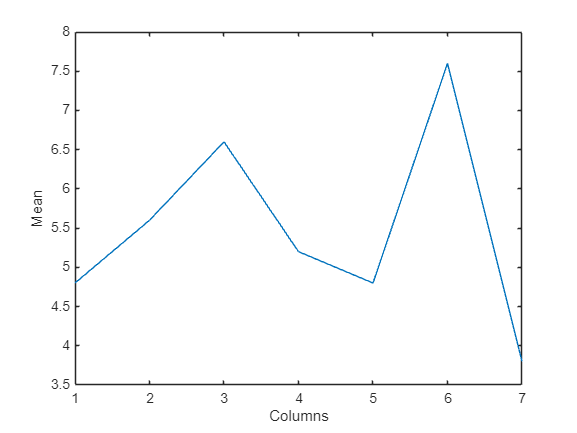

% First find the mean of each column in the matrix and store this information in the variable Avg 
% This variable will be used to create a line plot
Avg = mean(B);

% Plot the mean of each column in matrix B using the plot function
% The first input 1:colB is for the x-axis and the second input is for the y-axis. 
plot(1:colB, Avg);

%The following commands add labels to each of the plot axes
%The name of the label must be within "" marks
xlabel("Columns")
ylabel("Mean") 

Since we are using the function **randi()** to generate a matrix with random values, the shape of the plot will be different from the example on Canvas. 

The documentation for the **plot()** function reveals different ways to change the appearance of the plot. Specifically, the **plot() **function can change the color of the line, the width of the line, and the linestyle. The tables below show some commonly used inputs:

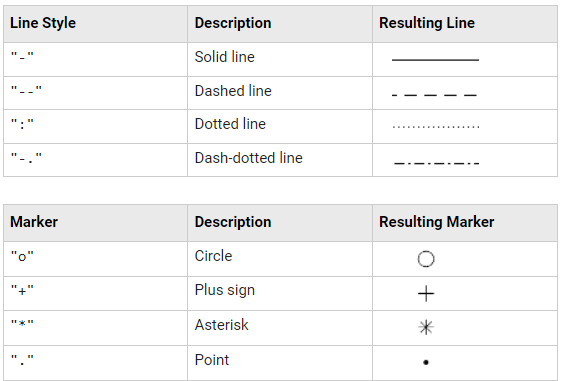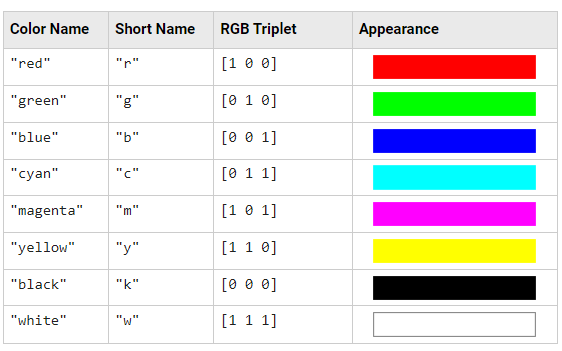

Lets use some of these parameters to change the style/appearance of the plot. 

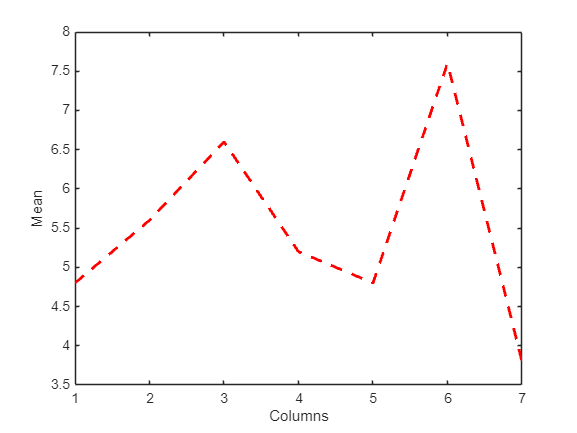

%The third input plot function below changes the line color to red and linestyle to dashed.
%The fourth input adjusts the width of the line
plot(1:colB, Avg, "r--", Linewidth=2)
xlabel("Columns")
ylabel("Mean")

Lets continue to adjust the plot by adding a title, making the font size 12, and changing the aspect ratio of the plot. Also, add a grid to the plot using the **grid on** command.

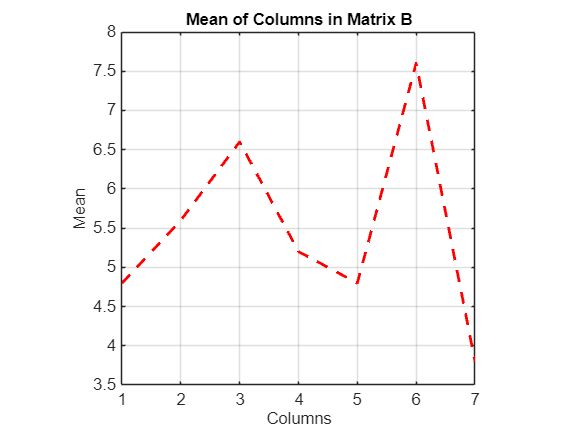

plot(1:colB, Avg, "r--", Linewidth=2)
xlabel("Columns")
ylabel("Mean")

% Adds a title to the top of the plot
title("Mean of Columns in Matrix B")

% Adjusts the fontsize of all the labels on the plot to 12
fontsize(12, "points")

% Controls the aspect ratio of the plot
% All the values are equal to 1 so plot will be a square
pbaspect([1 1 1])

% Adds some grid lines to the plot to make it easier to read
grid on

**Discussion Questions:**

- If we wanted to create plots about artists and athlete data, what data might we use?

- How might plots be helpful when trying to explain the importance of our data or conclusions from our AI tool?

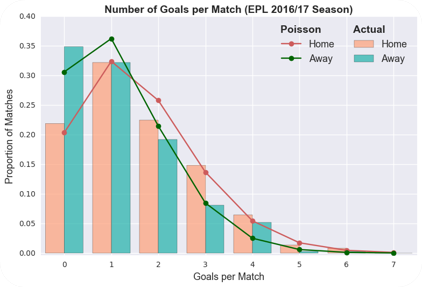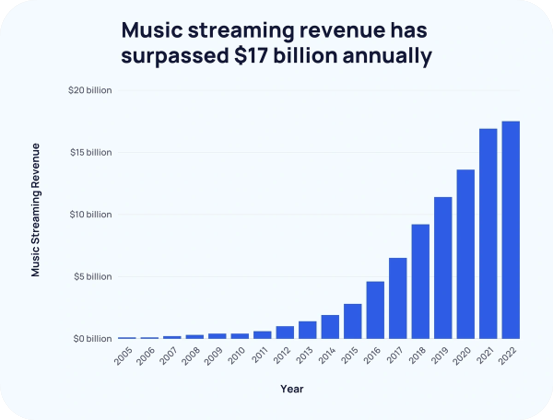

## Part 2: Import Data

Let's learn how we can import real-world data to create plots in order to make some inferences and conclusions based on our data. Make sure you have the data file 'Music2018.xlsx' for this section in the same folder as your live script (or if you are in the MATLAB Drive, it will be in the Data folder and you do not need to move it).

You can import data into MATLAB by using the **"Import Data"** button under the HOME tab. 

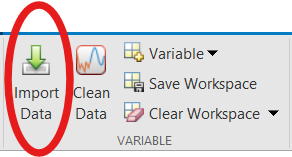

The **“Import Data”** button allows the user to extract data from MATLAB compatible files stored on their device. Selecting a file opens a window like the one shown below. In this window, the user can adjust the range of the data extracted and change the data output type. To import the selected data the user can use the “**Import Selection”** button. The imported data is stored in a variable that appears in the workspace. Once the variable is in the workspace the user can access the data to use in the code.

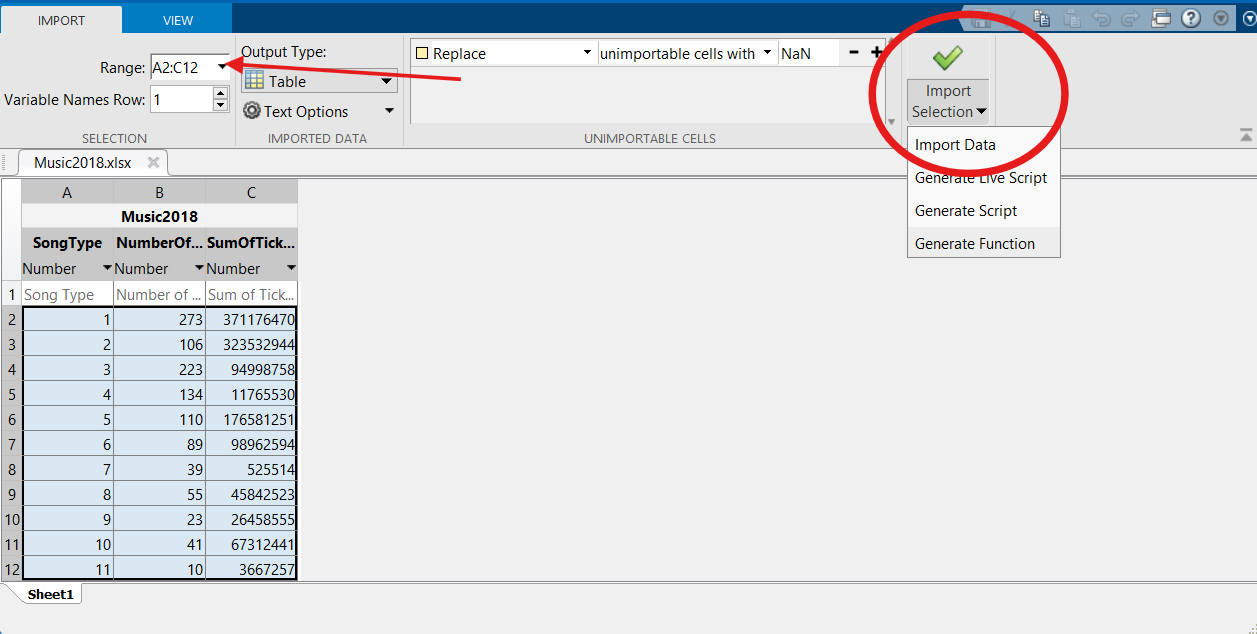

Another way to access data in MATLAB compatible files is to make sure that the file is in the same folder as your MATLAB live script. You can then use the **readtable()** function to import tabular data from a spreadsheet or text file, and store the data in variable.

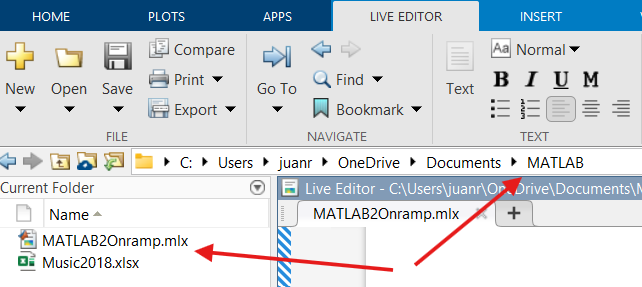

We can then store the data from this file in a table variable using the code below: 

%This code imports the data from the spreadsheet Movies2018.xlsx and stores
%it in a table variable called theater
Music = readtable('/MATLAB Drive/MATLAB - Section 02 (Student - File Share)/ML_Sec02(Part 1)-Continuing_MATLAB_Onramp/Data/Music2018.xlsx')

Music = 11x3 table
    SongType    NumberOfSongs    SumOfTicketsSold
    ________    _____________    ________________

        1            273            3.7118e+08   
        2            106            3.2353e+08   
        3            223            9.4999e+07   
        4            134            1.1766e+07   
        5            110            1.7658e+08   
        6             89            9.8963e+07   
        7             39            5.2551e+05   
        8             55            4.5843e+07   
        9             23            2.6459e+07   
       10             41            6.7312e+07   
       11             10            3.6673e+06   


We can use dot notation to refer to any individual variable within a table. We can also use dot notation to extract, modify, and reassign variables in a table. For example, the code `Music.NumberOfSongs = Music.NumberOfSongs + 100``; `adds 100 to each value the in the `NumberOfSongs `column of the table .

Music.NumberOfSongs = Music.NumberOfSongs + 100    

Music = 11x3 table
    SongType    NumberOfSongs    SumOfTicketsSold
    ________    _____________    ________________

        1            373            3.7118e+08   
        2            206            3.2353e+08   
        3            323            9.4999e+07   
        4            234            1.1766e+07   
        5            210            1.7658e+08   
        6            189            9.8963e+07   
        7            139            5.2551e+05   
        8            155            4.5843e+07   
        9            123            2.6459e+07   
       10            141            6.7312e+07   
       11            110            3.6673e+06   


We can also store individual columns from the table as variables, here are a couple ways to do this:

**Method 1. **

% This line of code extracts the variable SumOfTicketsSold from the table Music 
% and stores the result in a new variable named Type.
Type = Music.SumOfTicketsSold     

Type =    371176470
   323532944
    94998758
    11765530
   176581251
    98962594
      525514
    45842523
    26458555
    67312441


**Method 2. **

% Another way to extract data that allows you to control from which
% rows the data is extracted from. In this case, only data from the first 5
% rows is extracted
Type2 =  Music(1:5, "SumOfTicketsSold")    

Type2 = 5x1 table
    SumOfTicketsSold
    ________________

       3.7118e+08   
       3.2353e+08   
       9.4999e+07   
       1.1766e+07   
       1.7658e+08   


**Discussion Questions:**

        1.How would MATLAB make it easy to manage large amounts of data for applications in either music or sports? (athlete data, song data, etc.)

        2.If you were given data on athletes that had a column for number of games anda column for total score, how would you find the average score per game of each player?

## Part 3: Logical Arrays & Programming Structures

Coding logic and control structures are important features that allow us to control the flow of our programs and make comparisons that can allow us to make choices such as running a certain piece of our code or skipping it.

Relational operators, such as `>`, `<`, `==`, and `~=` perform comparisons between two values. The outcome of a comparison for equality or inequality is either `1` (`true`) or `0` (`false`). When comparing an array to a single scalar value the output is a logical array of ones and zeros. 

Here is an example of comparing a single integer to an array of integers, which gives us an array of true and false values (1s and 0s):

% Compares a 4-element vector to a single scalar value
% The output is a logical array the same size as the original vector
[5 27 1 15] > 12     

ans = 1x4 logical array
   0   1   0   1


A logical array can be used as an array index, so that MATLAB extracts the array elements where the corresponding index is `1` (`true`). This example extracts all elements of that are less than 10 from the vector A1:

% Create vector A1
A1 = [8 15 7 38 68 2 4 67 7];

% Extracts all the values less than 10 and stores them in Z
Z = A1(A1 < 10)

Z =      8     7     2     4     7


Logical Indexing can be used to reassign values in an array. It is also possible to combine logical comparisons by using the logical operators AND (&) and OR (|):

**Example 1:**

% Replaces all the values less than 10 with 10
A1(A1 < 10) = 10     

A1 =     10    15    10    38    68    10    10    67    10


**Example 2:**

% Finds numbers greater than 10 and less than 50
Y = A1(A1 > 10 & A1 < 50)     

Y =     15    38


**Discussion Question:**

- When would using a logical array or filter be useful for sorting sports data? Could we use this to narrow down the worst or best players/teams?

### If statements

One useful application of relational operators and logical arrays is in programming structures such as if statements and for loops. If statements allow you to perform conditional execution, where code is only executed when specific conditions are true. The basic syntax  is shown below.

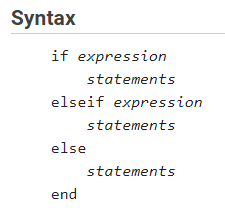

Below is a basic example of an if statement that takes the square root of an integer only if its greater than 50. Run this section of code multiple times to see if the code works properly.

% Generates a random integers between 0 and 100
x = randi([0 100])

x = 82

if x >= 50              % Condition required
    xSqrt = sqrt(x);    % Results of the operation are stored in a varible
    fprintf("The square root is: %d\n", xSqrt)
else                    % If the initial condition is not true a message is printed
    fprintf("This integer is not valid!") 
end                     % Always remember to add end, so that the code works

The square root is: 9.055385e+00


More complexity can be add to the if statement above by including elseif statements. Elseif statements allow you to check for more conditions and there is no limit to how many elseif statements you can incorporate. 

Lets add another condition to the example above. If the number is less than 50 and greater than 10 it will be squared:

% Generates a random integers between 0 and 100
x = randi([0 100])

x = 24

if x >= 50              % Condition required
    xSqrt = sqrt(x);    % Results of the operation are stored in a varible
    fprintf("The square root is: %d", xSqrt)
elseif x < 50 && x>10   % Additonal conditions
    xSqd = x^2;
    fprintf("The squared number is: %d", xSqd)
else                    % If the initial condition is not true a message is printed
    fprintf("This integer is not valid!") 
end                     % Always remember to add end, so that the code works 

The squared number is: 576

### For loops

For loops are used when you want to repeat a task for a specific number of times. Its syntax is shown below:

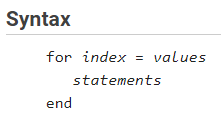

The index is written in the form of a row vector and it dictates how many times the statements are executed. For example, the index 1:25 will start at 1 and increase by 1 after each execution until it reaches 25, so the loop will be executed 25 times. 

**Example: How many runs will a for loop with the index 2:2:10 execute?**

The index will start out at 2 and increase by 2 until it reaches 10. Therefore, the resulting vector will be [2 4 6 8 10]. The vector contains 5 elements, so the for loop will be executed 5 times. 

%example for loop
for i = 2:2:10 %start at 2, go in steps of 2, end at 10
    disp(i) %prints out the variable 'i' on each loop through
end %ends the for loop

     2

     4

     6

     8

    10



The coding example below incorporates a for loop and if statements to calculate the square root of a number less than or equal to 50 and store it in a new vector. Use the step through capability in MATLAB to visualize how the code works. In the workspace see how the variable nVector is changing after each iteration. 

To step through the code click the numbers corresponding to the first and last lines of the code segment to make them red. Then click the "Run Section" button and use the "Step" button to step through each line of code one at a time. 

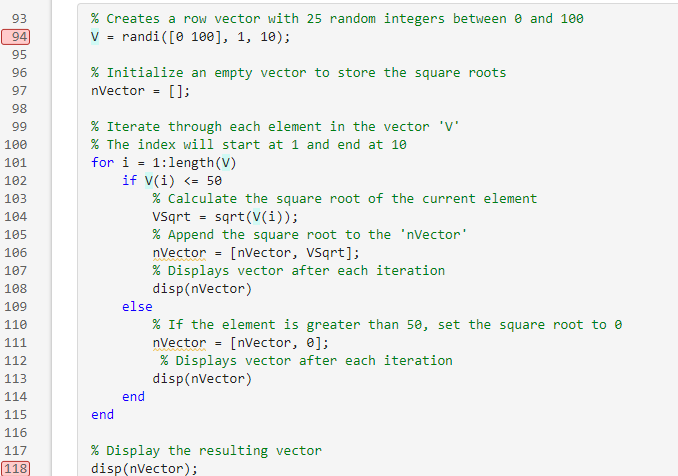

Here is the code for this example:

% Creates a row vector with 25 random integers between 0 and 100
V = randi([0 100], 1, 10)

V =     93    35    19    25    62    47    35    83    59    55



% Initialize an empty vector to store the square roots
nVector = [];

% Iterate through each element in the vector 'V'
% The index will start at 1 and end at 10
for i = 1:length(V)
    if V(i) <= 50
        % Calculate the square root of the current element
        VSqrt = sqrt(V(i));
        % Append the square root to the 'nVector'
        nVector = [nVector, VSqrt];
        % Displays vector after each iteration
        disp(nVector)
    else
        % If the element is greater than 50, set the square root to 0
        nVector = [nVector, 0];
         % Displays vector after each iteration
        disp(nVector)
    end
end

     0



         0    5.9161

         0    5.9161    4.3589

         0    5.9161    4.3589    5.0000



         0    5.9161    4.3589    5.0000         0



         0    5.9161    4.3589    5.0000         0    6.8557

         0    5.9161    4.3589    5.0000         0    6.8557    5.9161



         0    5.9161    4.3589    5.0000         0    6.8557    5.9161         0

         0    5.9161    4.3589    5.0000         0    6.8557    5.9161         0         0

         0    5.9161    4.3589    5.0000         0    6.8557    5.9161         0         0         0



% Display the resulting vector
disp(nVector);

         0    5.9161    4.3589    5.0000         0    6.8557    5.9161         0         0         0

